# 31383 Robotics Project

% Each segment can be run individually
% If there is some error, please clear the variables(run this segment) and run the segment
% individually
clear all;close all;clc;
load('answer.mat');
global answer GM m1 m2 m3 m4 L1 L2 dd2 L3 a4 I2 I3 I4 I1yy I2zz I3yy g n kT feff d1;

## question 1

syms theta1 theta2 theta4 d1 a4 d3
% rotation matrix
R01=[cos(theta1) -sin(theta1) 0;sin(theta1) cos(theta1) 0;0 0 1]*[1 0 0;0 0 1;0 -1 0];
R12=[cos(theta2) -sin(theta2) 0;sin(theta2) cos(theta2) 0;0 0 1]*[0 0 1;1 0 0;0 1 0];
R23=[-1 0 0;0 0 1;0 1 0];
R34=[cos(theta4) -sin(theta4) 0;sin(theta4) cos(theta4) 0;0 0 1]*[0 0 1;1 0 0;0 1 0];
% translation matrix
O01=[0;0;1.5];
O12=[0;0;0];
O23=[0;0;d3];
O34=[-1.02*sin(theta4);1.02*cos(theta4);0];
% homogenious matrix
T01=[R01,O01;0 0 0 1];
T12=[R12,O12;0 0 0 1];
T23=[R23,O23;0 0 0 1];
T34=[R34,O34;0 0 0 1];
T02=simplify(T01*T12);
T03=simplify(T02*T23);
T = simplify(T01*T12*T23*T34);
clearvars -except T;
syms theta1 theta2 theta4 q3;
syms pi;
% according to D-H rules
A = trans(theta1, theta2, q3, theta4, pi)

$$A = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{4}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{4}\right) & -\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{4}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{2}\right) & \frac{51\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{4}\right)}{50}+q_{3}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\frac{51\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{4}\right)}{50}\\ \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{4}\right)-\cos\left(\theta_{2}\right)\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & -\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)-\cos\left(\theta_{4}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \frac{51\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{4}\right)}{50}+q_{3}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\frac{51\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{1}\right)}{50}\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{4}\right)+\cos\left(\theta_{4}\right)\,\sin\left(\theta_{2}\right) & 0 & \sin\left(\theta_{2}\right)\,\sin\left(\theta_{4}\right)-\cos\left(\theta_{2}\right)\,\cos\left(\theta_{4}\right) & \frac{51\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{4}\right)}{50}+\frac{51\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{2}\right)}{50}+q_{3}\,\cos\left(\theta_{2}\right)+\frac{3}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% wrap up
answer.q1 = A;
clearvars -except answer GM m1 m2 m3 m4 L1 L2 dd2 L3 a4 I2 I3 I4 I1yy I2zz I3yy g n kT feff d1;


## question 2

%qv = inverkine(X,P);

## question 3

delta_P = [1.4 0 0.2 0];
% given X and P
X1 = [0 0 -1 0];P1 = [0 -0.5 0 1]+delta_P;
X2 = [0 0 -1 0];P2 = [0.35 0.5 0 1]+delta_P;
X3 = [0 0 -1 0];P3 = [0.7 -0.5 0 1]+delta_P;
X4 = [0 0 -1 0];P4 = [1.05 0.5 0 1]+delta_P;
X5 = [0 0 -1 0];P5 = [1.4 -0.5 0 1]+delta_P;
% qv means the joint variables
qv1 = inverkine(X1,P1)
qv2 = inverkine(X2,P2)

qv2 =     0.2783    1.7234    1.8414    2.9889


qv3 = inverkine(X3,P3)

qv3 =    -0.2337    1.6998    2.1768    3.0126


qv4 = inverkine(X4,P4)

qv4 =     0.2013    1.6823    2.5161    3.0301


qv5 = inverkine(X5,P5)

qv5 =    -0.1767    1.6689    2.8580    3.0435


% wrap up
answer.q3.qv1 = qv1;
answer.q3.qv2 = qv2;
answer.q3.qv3 = qv3;
answer.q3.qv4 = qv4;
answer.q3.qv5 = qv5;
clearvars -except answer GM m1 m2 m3 m4 L1 L2 dd2 L3 a4 I2 I3 I4 I1yy I2zz I3yy g n kT feff d1;

## question 4

for i = 1:4  % i means different segment
    % note that the vel and acc in knot points are 0
    % the displacements are from the last question
    % 6 equations(2 dis,2 vel,2 acc) -> 6 parameters
    seg_name = 'segment'+string(i);
    start_qv = 'answer.q3.qv'+string(i);% t=0
    end_qv = 'answer.q3.qv'+string(i+1);% t=2
    for j = 1:4
        name = 'a'+string(j);
        eval('v1='+start_qv+'('+string(j)+');');
        eval('v2='+end_qv+'('+string(j)+');');
        eval(seg_name+'.'+name+'= knot_p(v1,v2)');
    end
end

segment1 = struct with fields:
    a1: [0.1165 -0.5825 0.7767 0 0 -0.3430]


segment1 = struct with fields:
    a1: [0.1165 -0.5825 0.7767 0 0 -0.3430]
    a2: [-0.0063 0.0314 -0.0419 0 0 1.7570]


segment1 = struct with fields:
    a1: [0.1165 -0.5825 0.7767 0 0 -0.3430]
    a2: [-0.0063 0.0314 -0.0419 0 0 1.7570]
    a3: [0.0616 -0.3082 0.4109 0 0 1.5127]


segment1 = struct with fields:
    a1: [0.1165 -0.5825 0.7767 0 0 -0.3430]
    a2: [-0.0063 0.0314 -0.0419 0 0 1.7570]
    a3: [0.0616 -0.3082 0.4109 0 0 1.5127]
    a4: [0.0063 -0.0314 0.0419 0 0 2.9554]


segment2 = struct with fields:
    a1: [-0.0960 0.4800 -0.6401 0 0 0.2783]


segment2 = struct with fields:
    a1: [-0.0960 0.4800 -0.6401 0 0 0.2783]
    a2: [-0.0044 0.0222 -0.0296 0 0 1.7234]


segment2 = struct with fields:
    a1: [-0.0960 0.4800 -0.6401 0 0 0.2783]
    a2: [-0.0044 0.0222 -0.0296 0 0 1.7234]
    a3: [0.0629 -0.3144 0.4192 0 0 1.8414]


segment2 = struct with fields:
    a1: [-0.0960 0.4800 -0.6401 0 0 0.2783]
    a2: [-0.0044 0.0222 -0.0296 0 0 1.7234]
    a3: [0.0629 -0.3144 0.4192 0 0 1.8414]
    a4: [0.0044 -0.0222 0.0296 0 0 2.9889]


segment3 = struct with fields:
    a1: [0.0816 -0.4079 0.5438 0 0 -0.2337]


segment3 = struct with fields:
    a1: [0.0816 -0.4079 0.5438 0 0 -0.2337]
    a2: [-0.0033 0.0164 -0.0218 0 0 1.6998]


segment3 = struct with fields:
    a1: [0.0816 -0.4079 0.5438 0 0 -0.2337]
    a2: [-0.0033 0.0164 -0.0218 0 0 1.6998]
    a3: [0.0636 -0.3181 0.4242 0 0 2.1768]


segment3 = struct with fields:
    a1: [0.0816 -0.4079 0.5438 0 0 -0.2337]
    a2: [-0.0033 0.0164 -0.0218 0 0 1.6998]
    a3: [0.0636 -0.3181 0.4242 0 0 2.1768]
    a4: [0.0033 -0.0164 0.0218 0 0 3.0126]


segment4 = struct with fields:
    a1: [-0.0709 0.3544 -0.4725 0 0 0.2013]


segment4 = struct with fields:
    a1: [-0.0709 0.3544 -0.4725 0 0 0.2013]
    a2: [-0.0025 0.0125 -0.0167 0 0 1.6823]


segment4 = struct with fields:
    a1: [-0.0709 0.3544 -0.4725 0 0 0.2013]
    a2: [-0.0025 0.0125 -0.0167 0 0 1.6823]
    a3: [0.0641 -0.3205 0.4274 0 0 2.5161]


segment4 = struct with fields:
    a1: [-0.0709 0.3544 -0.4725 0 0 0.2013]
    a2: [-0.0025 0.0125 -0.0167 0 0 1.6823]
    a3: [0.0641 -0.3205 0.4274 0 0 2.5161]
    a4: [0.0025 -0.0125 0.0167 0 0 3.0301]


% wrap up
answer.q4.seg1 = segment1;
answer.q4.seg2 = segment2;
answer.q4.seg3 = segment3;
answer.q4.seg4 = segment4;
clearvars -except answer GM m1 m2 m3 m4 L1 L2 dd2 L3 a4 I2 I3 I4 I1yy I2zz I3yy g n kT feff d1;

## question 5

delta_d = [1.4 0];
% the last column of T indicates X and Y
d1 = [0 -0.5]+delta_d;
d2 = [0.35 0.5]+delta_d;
d3 = [0.7 -0.5]+delta_d;
d4 = [1.05 0.5]+delta_d;
d5 = [1.4 -0.5]+delta_d;
name_bin = {'x','y'};
for i = 1:4
    % note that the vel and acc in knot points are 0
    % t=0, X=X1; t=2, X=X2
    % 6 equations(2 dis,2 vel,2 acc) -> 6 parameters
    seg_name = 'segment'+string(i);
    start_qv = 'd'+string(i);
    end_qv = 'd'+string(i+1);
    for j = 1:2
        name = name_bin(j);
        eval('v1='+start_qv+'('+string(j)+');');
        eval('v2='+end_qv+'('+string(j)+');');
        eval(seg_name+'.'+name+'= knot_p(v1,v2)');
    end
end

segment1 = struct with fields:
    x: [0.0656 -0.3281 0.4375 0 0 1.4000]


segment1 = struct with fields:
    x: [0.0656 -0.3281 0.4375 0 0 1.4000]
    y: [0.1875 -0.9375 1.2500 0 0 -0.5000]


segment2 = struct with fields:
    x: [0.0656 -0.3281 0.4375 0 0 1.7500]


segment2 = struct with fields:
    x: [0.0656 -0.3281 0.4375 0 0 1.7500]
    y: [-0.1875 0.9375 -1.2500 0 0 0.5000]


segment3 = struct with fields:
    x: [0.0656 -0.3281 0.4375 0 0 2.1000]


segment3 = struct with fields:
    x: [0.0656 -0.3281 0.4375 0 0 2.1000]
    y: [0.1875 -0.9375 1.2500 0 0 -0.5000]


segment4 = struct with fields:
    x: [0.0656 -0.3281 0.4375 0 0 2.4500]


segment4 = struct with fields:
    x: [0.0656 -0.3281 0.4375 0 0 2.4500]
    y: [-0.1875 0.9375 -1.2500 0 0 0.5000]


% wrap up
answer.q5.seg1 = segment1;
answer.q5.seg2 = segment2;
answer.q5.seg3 = segment3;
answer.q5.seg4 = segment4;
clearvars -except answer GM m1 m2 m3 m4 L1 L2 dd2 L3 a4 I2 I3 I4 I1yy I2zz I3yy g n kT feff d1;


## question 6

syms theta1 theta2 theta4 d1 a4 d3
%[d,v,a] = polynom(answer.q5.seg1.x);
%[q,~,~] = polynom(answer.q4.seg1.a1);
% rotation matrix
R01=[cos(theta1) -sin(theta1) 0;sin(theta1) cos(theta1) 0;0 0 1]*[1 0 0;0 0 1;0 -1 0];
R12=[cos(theta2) -sin(theta2) 0;sin(theta2) cos(theta2) 0;0 0 1]*[0 0 1;1 0 0;0 1 0];
R23=[-1 0 0;0 0 1;0 1 0];
R34=[cos(theta4) -sin(theta4) 0;sin(theta4) cos(theta4) 0;0 0 1]*[0 0 1;1 0 0;0 1 0];
% translation matrix
O01=[0;0;1.5];
O12=[0;0;0];
O23=[0;0;d3];
O34=[-1.02*sin(theta4);1.02*cos(theta4);0];
% homogenious matrix
T01=[R01,O01;0 0 0 1];
T12=[R12,O12;0 0 0 1];
T23=[R23,O23;0 0 0 1];
T34=[R34,O34;0 0 0 1];
J = jacobi(T01,T12,T23,T34)

$$J = \begin{array}{l} \left(\begin{array}{cccc} -\frac{\sin\left(\theta_{1}\right)\,\sigma_{2}}{50} & -\cos\left(\theta_{1}\right)\,\sigma_{1} & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & -\frac{51\,\sin\left(\theta_{2}+\theta_{4}\right)\,\cos\left(\theta_{1}\right)}{50}\\ \frac{\cos\left(\theta_{1}\right)\,\sigma_{2}}{50} & -\sin\left(\theta_{1}\right)\,\sigma_{1} & \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & -\frac{51\,\sin\left(\theta_{2}+\theta_{4}\right)\,\sin\left(\theta_{1}\right)}{50}\\ 0 & -\frac{\sigma_{3}}{50}-d_{3}\,\cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & -\frac{\sigma_{3}}{50}\\ 0 & -\sin\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right)\\ 0 & \cos\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right)\\ 1 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{51\,\sin\left(\theta_{2}+\theta_{4}\right)}{50}+d_{3}\,\sin\left(\theta_{2}\right)\\ \sigma_{2}=\sigma_{3}+50\,d_{3}\,\cos\left(\theta_{2}\right)\\ \sigma_{3}=51\,\cos\left(\theta_{2}+\theta_{4}\right) \end{array}$$

j = simplify(det(transpose(J)*J)) % the det of the pesudo inverse matrix

$$j = \frac{{d_{3}}^{2}\,\left(2601\,\cos\left(2\,\theta_{2}+2\,\theta_{4}\right)+2500\,{d_{3}}^{2}\,\cos\left(2\,\theta_{2}\right)+5100\,d_{3}\,\cos\left(\theta_{4}\right)+2500\,{d_{3}}^{2}+5100\,d_{3}\,\cos\left(2\,\theta_{2}+\theta_{4}\right)+7601\right)}{5000}$$

s = @(x) 2601*cos(2*(x(1)+x(3)))+2500*x(2)^2*cos(2*x(1))+5100*x(2)*cos(x(3))+2500*x(2)^2+5100*x(2)*cos(2*x(1)+x(3))+7601;
x = fmincon(s,[pi/6,1.35,-pi/2],[],[],[],[],[pi/6,1.35,-pi/2],[3*pi/4,3,5*pi/4]);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


s(x)

ans = 5.0000e+03

answer.q6.J = J;
clearvars -except answer GM m1 m2 m3 m4 L1 L2 dd2 L3 a4 I2 I3 I4 I1yy I2zz I3yy g n kT feff d1;

## question 7

% link1
m1 = 4.9;r1 = 0.04;L1 = 0.67;
I1 = m1/12*(3*r1^2+L1^2)

I1 = 0.1853

I1yy = 0.5*m1*r1^2

I1yy = 0.0039

% link2
m2 = 8.1;b2 = 0.22;L2 = 1.7;
I2 =1/12*m2*(L2^2+b2^2)

I2 = 1.9834

I2zz =1/12*m2*(b2^2+b2^2)

I2zz = 0.0653

% link3
m3 = 4.9;b3 = 0.18;L3 = 1.65;
I3 = 1/12*m3*(L3^2+b3^2)

I3 = 1.1249

I3yy =1/12*m3*(b3^2+b3^2)

I3yy = 0.0265

% link4
m4 = 2.2;a4 = 0.98;
I4 = 1/12*m4*a4^2

I4 = 0.1761

% store the answer
answer.q7.I1 = I1;
answer.q7.I1yy = I1yy;
answer.q7.I2 = I2;
answer.q7.I2zz = I2zz;
answer.q7.I3 = I3;
answer.q7.I3yy = I3yy;
answer.q7.I4 = I4;
clearvars -except answer GM m1 m2 m3 m4 L1 L2 dd2 L3 a4 I2 I3 I4 I1yy I2zz I3yy g n kT feff d1;

## question 8

%simulink(ans8.slx);

## question 9

## Ergodic method

% syms pi
% m1 = 4.9;
% m2 = 8.1;
% m3 = 4.9;
% m4 = 2.2;
% 
% r1 = 0.04;
% L1 = 0.67;
% 
% b2 = 0.22;
% L2 = 1.7;
% 
% b3 = 0.18;
% L3 = 1.65;
% 
% L4 = 0.98;
% a4 = L4;
% 
% I1 = 1/12*m1*(3*r1^2+L1^2);
% I1yy = 1/2*m1*r1^2;
% I1zz = I1;
% 
% I2 = 1/12*m2*(b2^2+L2^2);
% I2zz = 1/12*m2*(b2^2*2);
% I2yy = I2;
% 
% I3 = 1/12*m3*(b3^2+L3^2);
% I3yy = 1/12*m3*(b3^2*2);
% I3zz = I3;
% 
% I4 = 1/12*m4*L4^2;
% I4yy = I4;
% I4xx = 0;
% 
% delta2 = 0.34;
% 
% A = [];
% i = 1;
% Dq = zeros(6,4456);
% D1 = 0;
% D2 = 0;
% Q1 = [0 0 0 0]';
% Q2 = [0 0 0 0]';
% %a = 1:1000:70000;
% lambda2 = 0.36;
% for q1 = -pi:pi/5:pi
%     for q2 = -pi/6:pi/5:3*pi/4
%         for q3 = 1.35:0.2:3.00
%             for q4 = -pi/2:pi/5:5*pi/4
%                 K0 = m2*(1/2*L2-lambda2)^2+m3*(1/2*L3)^2;
%                 K1 = 1/2*(I4 + 1/4 * m4 * a4^2);
%                 K2 = 1/2*(I2 - I2zz + I3 - I3yy + K0);
%                 K3 = I2 + I3 + K0 + 2 * K1;
%                 K4 = m3 +m4;
%                 K5 = 1/2*(2 * I1yy + I2zz + I3yy + K3);
%                 f1 = 1/2 * K4 * q3^2-1/2 * m3 * L3 * q3;
%                 f2 = m4 * a4 * q3;
%                 f = 1/2 * a4 * m4 * cos(q4);
%                 D11 = K5 + f1 - (K2 + f1)*cos(2*q2) + K1*cos(2*(q2+q4)) - f2*cos(q2+q4)*sin(q2);
%                 Dq1 = [D11 0                     0   0;
%                     0   K3+2*f1+f2*sin(q4)    f   2*K1+1/2*f2*sin(q4);
%                     0    f                    K4  f;
%                     0    2*K1+1/2*f2*sin(q4)  f   2*K1];
%                 
%                 %                 Dq1 = [D11  0                     0   0;
%                 %                        0    K3+2*f1+f2*sin(q4)    0   0;
%                 %                        0    0                     0   0;
%                 %                        0    0                     0   0];
%                 if Dq1(1,1) > D1
%                     D1 = Dq1(1,1);
%                     Q1 = [q1 q2 q3 q4]';
%                 end
%                 if Dq1(2,2) >D2
%                     D2 = Dq1(2,2);
%                     Q2 = [q1 q2 q3 q4]';
%                 end
%                 i = i+1;
%             end
%         end
%     end
% end
% 
% D1 = vpa(D1);
% Q1;
% 
% D2 = vpa(D2);
% Q2;
% Dq1
% D3=K4
% D4=K2*K1+1/2*f2*1
% n = 53;
% JM = 1320e-7;
% Jeff = [(1/n^2)*D1+JM;
%     (1/n^2)*D2+JM;
%     (1/n^2)*D3+JM;
%     (1/n^2)*D4+JM;]
% vpa(Jeff)
% clearvars -except answer GM m1 m2 m3 m4 L1 L2 dd2 L3 a4 I2 I3 I4 I1yy I2zz I3yy g n kT feff d1;

## Partial diff method

% initialize parameters
L1 = 0.67;r1=0.04;L2=1.7;b2=0.22;L3=1.65;b3=0.18;
a4=0.98;m1=4.9;m2=8.1;m3=4.9;m4=2.2;delta_2=0.34;
J_m=1320e-7;
n=53;
I1 = answer.q7.I1;
I1yy = answer.q7.I1yy;
I2 = answer.q7.I2;
I2zz = answer.q7.I2zz;
I3 = answer.q7.I3;
I3yy = answer.q7.I3yy;
I4 = answer.q7.I4;
% Annex B
K0=m2*(L2/2-delta_2)^2+m3*(L3/2)^2;
K1=(I4+m4*a4^2/4)/2;
K2=(I2-I2zz+I3-I3yy+K0)/2;
K3=I2+I3+K0+2*K1;
K4=m3+m4;
K5=(2*I1yy+I2zz+I3yy+K3)/2;
f1=@(q3)(K4*q3^2-m3*L3*q3)/2;
f2=@(q3)m4*a4*q3;
f=@(q4)a4*m4*cos(q4)/2;

syms q1 q2 q3 q4
% let's define x(1), x(2), x(3) is q2,q3,q4 respectively
D11=@(x)-(K5+f1(x(2))-(K2+f1(x(2)))*cos(2*x(1))+K1*cos(2*(x(1)+x(3)))-f2(x(2))*cos(x(1)+x(3))*sin(x(1)));
% let's define x(1), x(2) is q3,q4 respectively
D22=@(x)-(K3+2*f1(x(1))+f2(x(1))*sin(x(2)));
% D11 and D22 should be positive, so -D11 and -D22 are negative, the
% maximun becomes the minimum
D33=K4;
D44=2*K1;
x0=[pi/6,1.35,-pi/2];% initial value of the joint variables
sup1=fmincon(D11,x0,[],[],[],[],[pi/6,1.35,-pi/2],[3*pi/4,3,5*pi/4]);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<<a href = "matlab: createExitMsg({'optimlib:sqpLineSearch:Exit1basic'},{'optimlib:sqpLineSearch:Exit1detailed','5.453901e-08','1.000000e-06','0.000000e+00','1.000000e-06'},true,true);;">stopping criteria details</a

sup_D11=-D11(sup1); % remember to turn it back
x0 = [1.35,-pi/2];
sup2=fmincon(D22,x0,[],[],[],[],[1.35,-pi/2],[3,5*pi/4]);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<<a href = "matlab: createExitMsg({'optimlib:sqpLineSearch:Exit1basic'},{'optimlib:sqpLineSearch:Exit1detailed','8.028911e-08','1.000000e-06','0.000000e+00','1.000000e-06'},true,true);;">stopping criteria details</a

sup_D22=-D22(sup2); %remember to turn it back
Dii = [sup_D11,sup_D22,D33,D44];
J_eff = zeros(4,1);
J_eff(1)=sup_D11/(n)^2+J_m;
J_eff(2)=sup_D22/(n)^2+J_m;
J_eff(3)=D33/(n)^2+J_m;
J_eff(4)=D44/(n)^2+J_m;
answer.q9.J_eff = J_eff;
answer.q9.Dii = Dii;
clearvars -except answer GM m1 m2 m3 m4 L1 L2 dd2 L3 a4 I2 I3 I4 I1yy I2zz I3yy g n kT feff d1;

## question 10

% see report

## question 11

% see report

## question 12

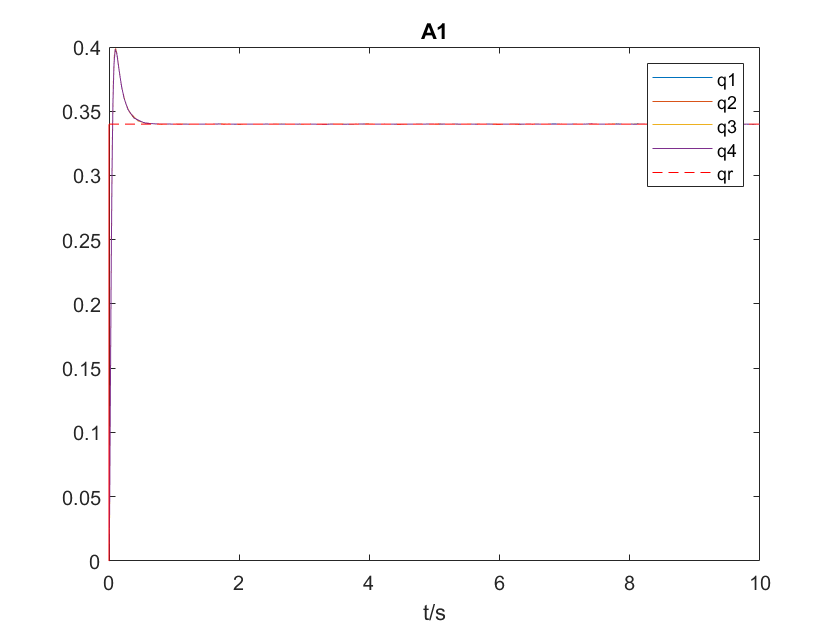

J_m=1320e-7;f_m = 2.4e-5;n=53;K_T = 0.17;g = 9.8;f_eff = 2.4e-5;
zeta=1;omega=15;T_L=0;
J_eff = answer.q9.J_eff;
K_P=@(J_effi,omega)omega^2*J_effi/K_T;
K_D=@(J_effi,omega,zeta) (2*zeta*omega*J_effi-f_eff)/K_T;
qr_i = 0.34;
figure;
time = [];
qi = [];
for i=1:4
    J_effi = J_eff(i);
    f_effi = f_eff;
    KP = K_P(J_effi,omega);
    KD = K_D(J_effi,omega,zeta);
    sim('ans12');
    plot(time,qi);
    hold on;
end
line([0,max(time)],[qr_i,qr_i],'Color','r','LineStyle','--');
hold on;
line([0,0],[0,qr_i],'Color','r');
hold on;
legend('q1','q2','q3','q4','qr');
title('A1');
xlabel('t/s');

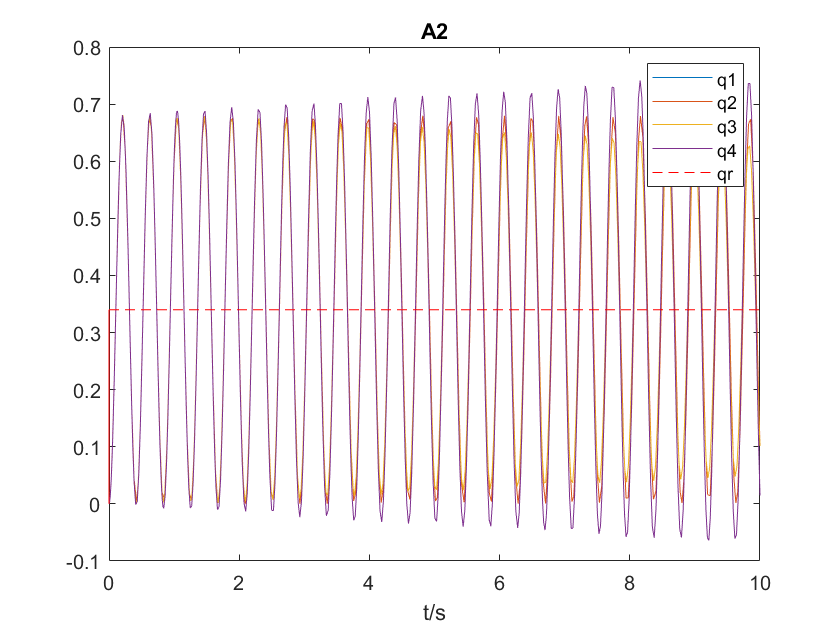

zeta=0;omega=15;T_L=0;
J_eff = answer.q9.J_eff;
K_P=@(J_effi,omega)omega^2*J_effi/K_T;
K_D=@(J_effi,omega,zeta) (2*zeta*omega*J_effi-f_eff)/K_T;
qr_i = 0.34;
figure;
time = [];
qi = [];
for i=1:4
    J_effi = J_eff(i);
    f_effi = f_eff;
    KP = K_P(J_effi,omega);
    KD = K_D(J_effi,omega,zeta);
    sim('ans12');
    plot(time,qi);
    hold on;
end
line([0,max(time)],[qr_i,qr_i],'Color','r','LineStyle','--');
hold on;
line([0,0],[0,qr_i],'Color','r');
hold on;
legend('q1','q2','q3','q4','qr');
title('A2');
xlabel('t/s');

clearvars -except answer;

## question 13

J_m=1320e-7;f_m = 2.4e-5;n=53;K_T = 0.17;g = 9.8;f_eff = 2.4e-5;
zeta=1;omega=15;
L1 = 0.67;r1=0.04;L2=1.7;b2=0.22;L3=1.65;b3=0.18;
a4=0.98;m1=4.9;m2=8.1;m3=4.9;m4=2.2;delta_2=0.34;
J_eff = answer.q9.J_eff;
K_P=@(J_effi,omega)omega^2*J_effi/K_T;
K_D=@(J_effi,omega,zeta) (2*zeta*omega*J_effi-f_eff)/K_T;
qr_i = 0.35;
% let's define h first
f_h_2 = @(x) -(0.5*m4*a4*cos(x(1)+x(3))+(m2*(delta_2-0.5*L2)+m3*(0.5*L3-x(2))-m4*x(2))*sin(x(1)));
p_2=fmincon(f_h_2,[pi/6,1.35,-pi/2],[],[],[],[],[pi/6,1.35,-pi/2],[3*pi/4,3,5*pi/4]);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<<a href = "matlab: createExitMsg({'optimlib:sqpLineSearch:Exit1basic'},{'optimlib:sqpLineSearch:Exit1detailed','2.279746e-07','1.000000e-06','0.000000e+00','1.000000e-06'},true,true);;">stopping criteria details</a

f_h_2 = @(x) (0.5*m4*a4*cos(x(1)+x(3))+(m2*(delta_2-0.5*L2)+m3*(0.5*L3-x(2))-m4*x(2))*sin(x(1)));
p_2=fmincon(f_h_2,[pi/6,1.35,-pi/2],[],[],[],[],[pi/6,1.35,-pi/2],[3*pi/4,3,5*pi/4]);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<<a href = "matlab: createExitMsg({'optimlib:sqpLineSearch:Exit1basic'},{'optimlib:sqpLineSearch:Exit1detailed','2.816901e-07','1.000000e-06','0.000000e+00','1.000000e-06'},true,true);;">stopping criteria details</a

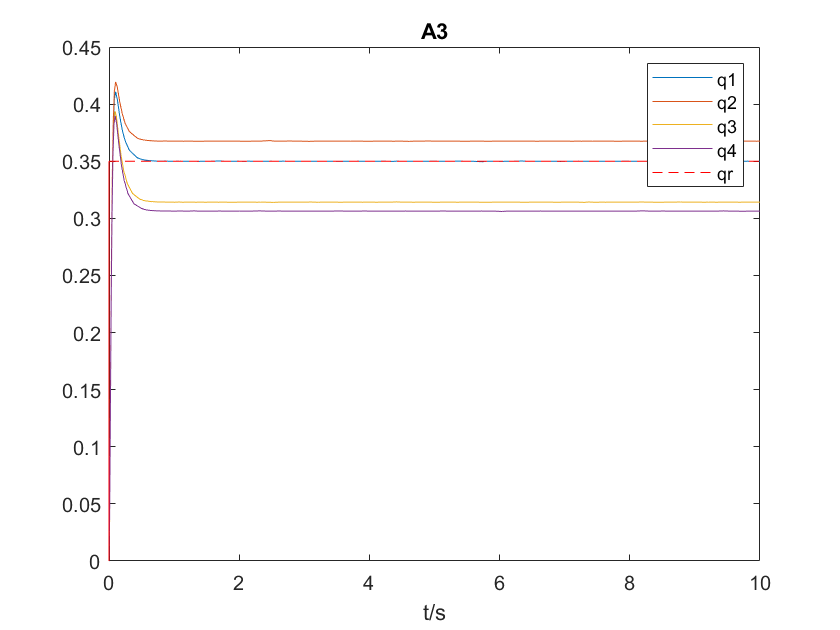

TL = [0,g*f_h_2(p_2),g*(m3+m4)*cos(pi/6),0.5*g*a4*m4];
figure;
time = [];
qi = [];
E_sso = zeros(1,4);
for i=1:4
    J_effi = J_eff(i);
    f_effi = f_eff;
    KP = K_P(J_effi,omega);
    KD = K_D(J_effi,omega,zeta);
    T_L = TL(i);
    sim('ans12');
    E_sso(i) = qr_i-qi(size(time,1));
    plot(time,qi);
    hold on;
end
line([0,max(time)],[qr_i,qr_i],'Color','r','LineStyle','--');
hold on;
line([0,0],[0,qr_i],'Color','r');
hold on;
legend('q1','q2','q3','q4','qr');
title('A3');
xlabel('t/s');

E_ss=zeros(1,4);
for i=1:4
    zeta=1;
    omega=15;
    KP=K_P(J_eff(i),omega);
    T_L=TL(i);
    E_ss(i)=T_L/(n^2*K_T*KP);
end
disp(E_ss);

         0   -0.0176    0.0358    0.0437



disp(E_sso);

   -0.0000   -0.0176    0.0358    0.0437



answer.q13.TL = TL;
clearvars -except answer GM m1 m2 m3 m4 L1 L2 dd2 L3 a4 I2 I3 I4 I1yy I2zz I3yy g n kT feff d1;

## question 14

% see in report

## question 15

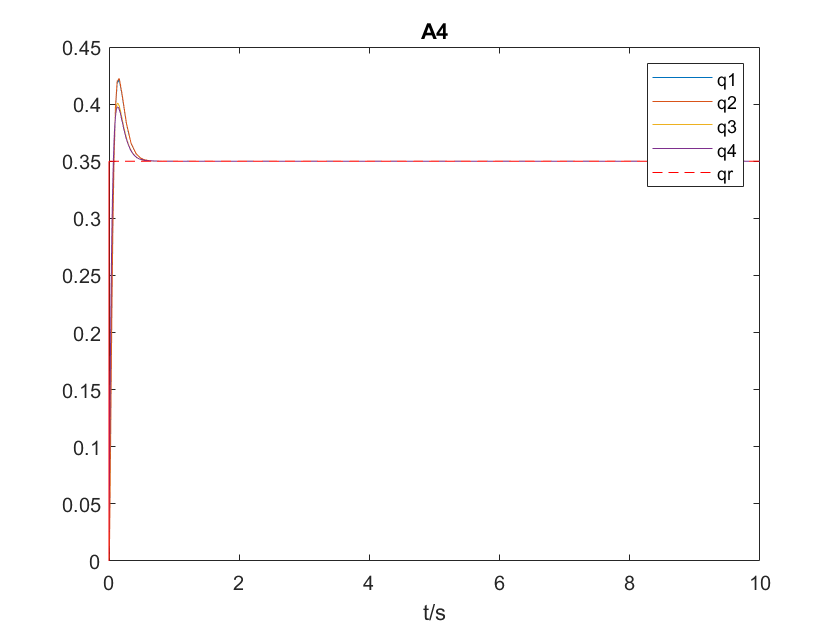

J_m=1320e-7;f_m = 2.4e-5;n=53;K_T = 0.17;g = 9.8;f_eff = 2.4e-5;
zeta=1;omega=15;qr_i = 0.35;
J_eff = answer.q9.J_eff;
TL = answer.q13.TL;
tau = abs(J_eff);
K_I = @(omega) omega^2/K_T;
K_P = @(omega,zeta,taui) (2*zeta*omega+taui*omega^2)/K_T;
K_D = @(omega,zeta,taui) (2*zeta*omega*taui+1-f_eff)/K_T;
figure;
time = [];
qi = [];
E_sso = zeros(1,4);
for i=1:4
    taui = tau(i);
    f_effi = f_eff;
    J_effi = J_eff(i);
    KP = K_P(omega,zeta,taui);
    KD = K_D(omega,zeta,taui);
    KI = K_I(omega);
    T_L = TL(i);
    sim('ans15',10);
    E_sso(i) = qr_i-qi(size(time,1));
    plot(time,qi);
    hold on;
end
line([0,max(time)],[qr_i,qr_i],'Color','r','LineStyle','--');
hold on;
line([0,0],[0,qr_i],'Color','r');
hold on;
legend('q1','q2','q3','q4','qr');
title('A4');
xlabel('t/s');

% the steady error of PID system is equal to 0
E_ss=zeros(1,4);
disp(E_ss);

     0     0     0     0



disp(E_sso);

   1.0e-04 *

   -0.1308   -0.1335   -0.0743    0.0000



clearvars -except answer GM m1 m2 m3 m4 L1 L2 dd2 L3 a4 I2 I3 I4 I1yy I2zz I3yy g n kT feff d1;

## question 16

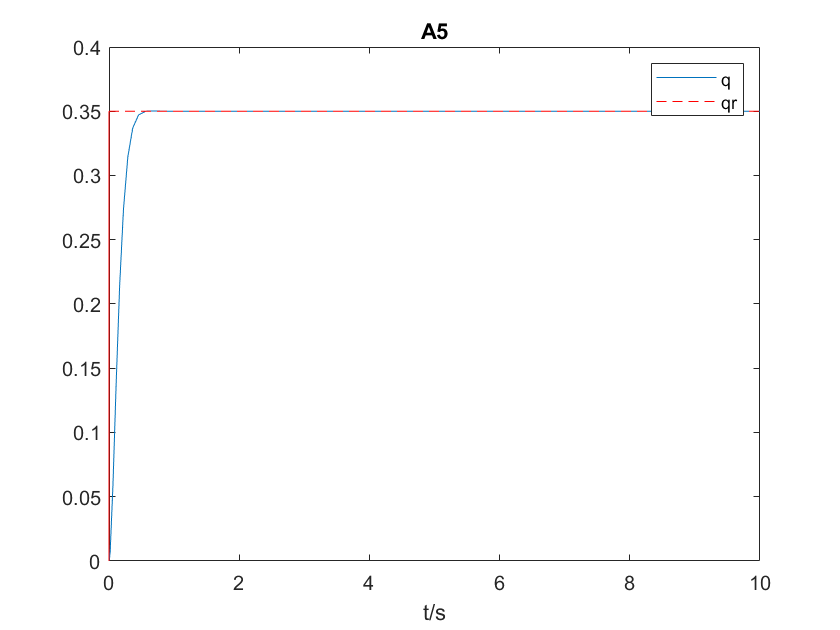

J_m=1320e-7;f_m = 2.4e-5;n=53;K_T = 0.17;g = 9.8;f_eff = 2.4e-5;
zeta=1;omega=15;qr_i = 0.35;
J_eff = answer.q9.J_eff;
TL = answer.q13.TL;
tau = abs(J_eff);
K_I = @(omega) omega^2/K_T;
K_P = @(omega,zeta,taui) (2*zeta*omega+taui*omega^2)/K_T;
K_D = @(omega,zeta,taui) (2*zeta*omega*taui+1-f_eff)/K_T;
figure;
time = [];
qi = [];
E_sso = zeros(1,4);
for i=1
    taui = tau(i);
    f_effi = f_eff;
    J_effi = J_eff(i);
    KP = K_P(omega,zeta,taui);
    KD = K_D(omega,zeta,taui);
    KI = K_I(omega);
    T_L = TL(i);
    sim('ans16_1',10);
    plot(time,qi);
    hold on;
end
line([0,max(time)],[qr_i,qr_i],'Color','r','LineStyle','--');
hold on;
line([0,0],[0,qr_i],'Color','r');
hold on;
legend('q','qr');
title('A5');
xlabel('t/s');

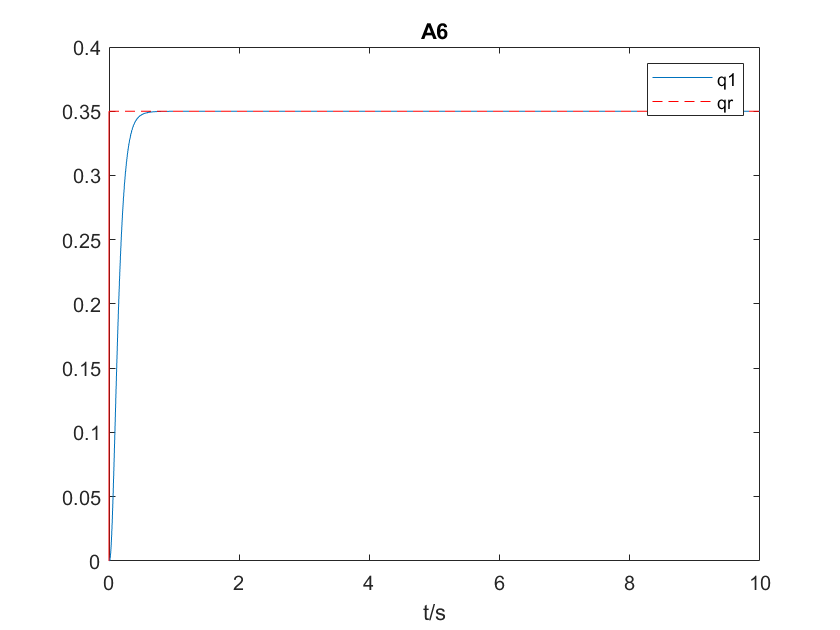

%symbolic system
figure;
time = [];
qi = [];
for i=1
    taui = tau(i);
    f_effi = f_eff;
    J_effi = J_eff(i);
    KP = K_P(omega,zeta,taui);
    KD = K_D(omega,zeta,taui);
    KI = K_I(omega);
    T_L = TL(i);
    sim('ans16_2',10);
    plot(time,qi);
    hold on;
end
line([0,max(time)],[qr_i,qr_i],'Color','r','LineStyle','--');
hold on;
line([0,0],[0,qr_i],'Color','r');
hold on;
legend('q1','qr');
title('A6');
xlabel('t/s');

clearvars -except answer GM m1 m2 m3 m4 L1 L2 dd2 L3 a4 I2 I3 I4 I1yy I2zz I3yy g n kT feff d1;

## question 17

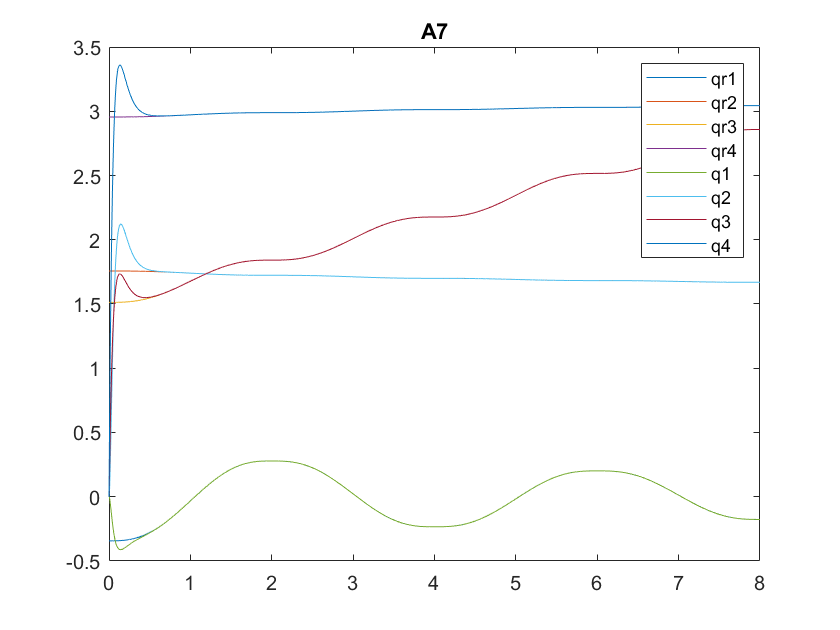

dd2 = 0.34;
I1yy = answer.q7.I1yy;
I2zz = answer.q7.I2zz;
I3yy = answer.q7.I3yy;
I2 = answer.q7.I2;
I3 = answer.q7.I3;
I4 = answer.q7.I4;
L1 = 0.67;L2=1.7;L3=1.65;
a4=0.98;m1=4.9;m2=8.1;m3=4.9;m4=2.2;kT = 0.17;feff=2.4e-5;g=9.8;n=53;d1=1.5;
J_eff = answer.q9.J_eff;
zeta=1;omega=15;
TL = answer.q13.TL;
tau = abs(J_eff);
K_I = @(omega) omega^2/kT;
K_P = @(omega,zeta,taui) (2*zeta*omega+taui*omega^2)/kT;
K_D = @(omega,zeta,taui) (2*zeta*omega*taui+1-feff)/kT;
KD=zeros(1,4);
KP=zeros(1,4);
KI=zeros(1,4);
for i=1:4
    KI(i)=K_I(omega);
    KD(i)=K_D(omega,zeta,tau(i));
    KP(i)=K_P(omega,zeta,tau(i));
end
GM = [answer.q4.seg1.a1;answer.q4.seg1.a2;answer.q4.seg1.a3;answer.q4.seg1.a4;answer.q4.seg2.a1;answer.q4.seg2.a2;answer.q4.seg2.a3;answer.q4.seg2.a4;answer.q4.seg3.a1;answer.q4.seg3.a2;answer.q4.seg3.a3;answer.q4.seg3.a4;answer.q4.seg4.a1;answer.q4.seg4.a2;answer.q4.seg4.a3;answer.q4.seg4.a4];
[t,x,y] = sim('ans17',8);
figure; 
for i=1:8
    plot(t,y(:,i));
    hold on;
end
title('A7');
legend('qr1','qr2','qr3','qr4','q1','q2','q3','q4');

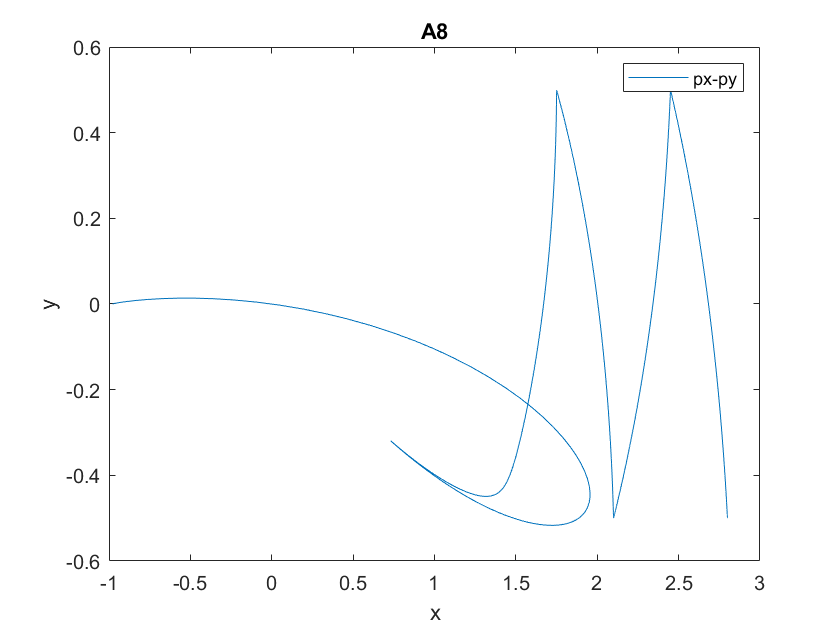

figure;
plot(y(:,9),y(:,10));
title('A8');
legend('px-py');
xlabel('x');
ylabel('y');

clearvars -except answer GM m1 m2 m3 m4 L1 L2 dd2 L3 a4 I2 I3 I4 I1yy I2zz I3yy g n kT feff d1;

## question 18

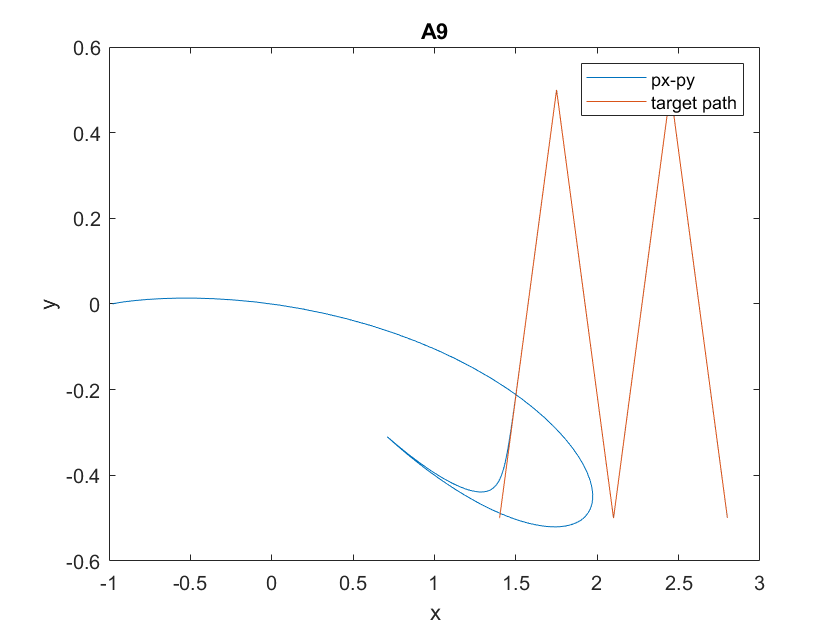

clear all;
load('answer.mat');
global answer GM m1 m2 m3 m4 L1 L2 dd2 L3 a4 I2 I3 I4 I1yy I2zz I3yy g n kT feff d1;
dd2 = 0.34;
I1yy = answer.q7.I1yy;
I2zz = answer.q7.I2zz;
I3yy = answer.q7.I3yy;
I2 = answer.q7.I2;
I3 = answer.q7.I3;
I4 = answer.q7.I4;
L1 = 0.67;L2=1.7;L3=1.65;
a4=0.98;m1=4.9;m2=8.1;m3=4.9;m4=2.2;kT = 0.17;feff=2.4e-5;g=9.8;n=53;d1=1.5;
J_eff = answer.q9.J_eff;
zeta=1;omega=15;
TL = answer.q13.TL;
tau = abs(J_eff);
K_I = @(omega) omega^2/kT;
K_P = @(omega,zeta,taui) (2*zeta*omega+taui*omega^2)/kT;
K_D = @(omega,zeta,taui) (2*zeta*omega*taui+1-feff)/kT;
KD=zeros(1,4);
KP=zeros(1,4);
KI=zeros(1,4);
for i=1:4
    KI(i)=K_I(omega);
    KD(i)=K_D(omega,zeta,tau(i));
    KP(i)=K_P(omega,zeta,tau(i));
end
GM = [answer.q5.seg1.x;answer.q5.seg1.y;answer.q5.seg2.x;answer.q5.seg2.y;answer.q5.seg3.x;answer.q5.seg3.y;answer.q5.seg4.x;answer.q5.seg4.y];
[t,x,y]=sim('ans18',8);
figure;
plot(y(:,9),y(:,10));
hold on;
plot(y(:,15),y(:,16));
legend('px-py','target path');
title('A9');
xlabel('x');
ylabel('y');

answer.q18 = y(:,[9,10,15,16]);
clearvars -except answer GM m1 m2 m3 m4 L1 L2 dd2 L3 a4 I2 I3 I4 I1yy I2zz I3yy g n kT feff d1;

## question 19

%see in report

## question 20

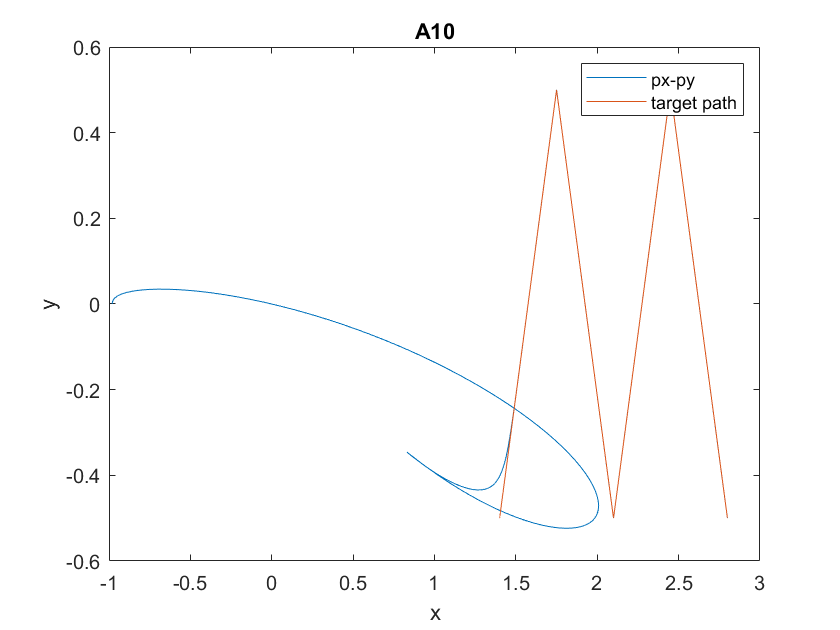

dd2 = 0.34;
I1yy = answer.q7.I1yy;
I2zz = answer.q7.I2zz;
I3yy = answer.q7.I3yy;
I2 = answer.q7.I2;
I3 = answer.q7.I3;
I4 = answer.q7.I4;
L1 = 0.67;L2=1.7;L3=1.65;
a4=0.98;m1=4.9;m2=8.1;m3=4.9;m4=2.2;kT = 0.17;feff=2.4e-5;g=9.8;n=53;d1=1.5;
J_eff = answer.q9.J_eff;
zeta=1;omega=15;
TL = answer.q13.TL;
tau = abs(J_eff);
K_I = @(omega) omega^2/kT;
K_P = @(omega,zeta,taui) (2*zeta*omega+taui*omega^2)/kT;
K_D = @(omega,zeta,taui) (2*zeta*omega*taui+1-feff)/kT;
KD=zeros(1,4);
KP=zeros(1,4);
KI=zeros(1,4);
for i=1:4
    eval('KI'+string(i)+'=K_I(omega);');
    eval('KD'+string(i)+'=K_D(omega,zeta,tau(i));');
    eval('Kp'+string(i)+'=K_P(omega,zeta,tau(i));');
end
GM = [answer.q5.seg1.x;answer.q5.seg1.y;answer.q5.seg2.x;answer.q5.seg2.y;answer.q5.seg3.x;answer.q5.seg3.y;answer.q5.seg4.x;answer.q5.seg4.y];
sim('trc_dyn',8);
figure;
plot(p(:,1),p(:,2));
hold on;
plot(pr(:,1),pr(:,2));
legend('px-py','target path');
title('A10');
xlabel('x');
ylabel('y');

y = answer.q18;
figure;
plot(y(:,1),y(:,2));
hold on;
plot(y(:,3),y(:,4));
legend('px-py','target path');
title('A9');
xlabel('x');
ylabel('y');

answer.q20 = [p(:,1),p(:,2),pr(:,1),pr(:,2)];
clearvars -except answer GM m1 m2 m3 m4 L1 L2 dd2 L3 a4 I2 I3 I4 I1yy I2zz I3yy g n kT feff d1;

## question 21

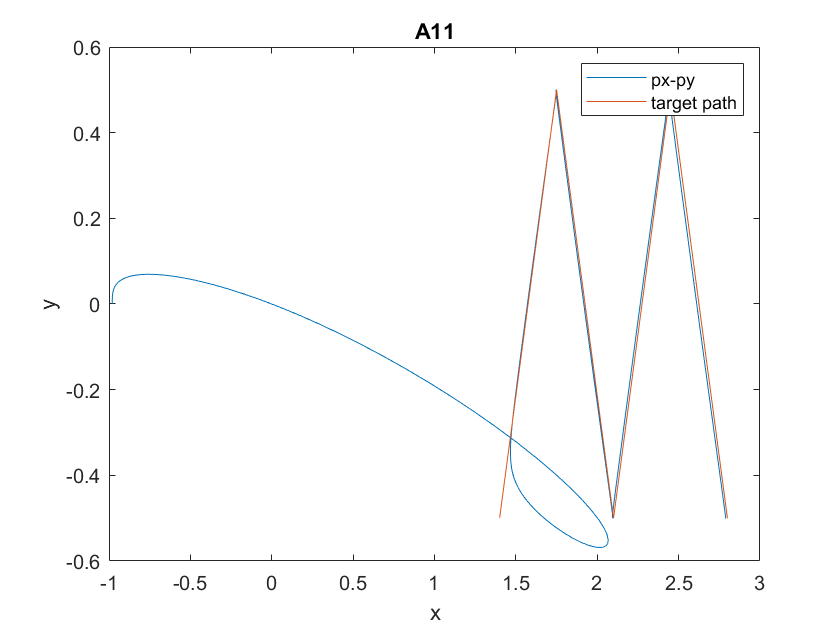

dd2 = 0.34;
I1yy = answer.q7.I1yy;
I2zz = answer.q7.I2zz;
I3yy = answer.q7.I3yy;
I2 = answer.q7.I2;
I3 = answer.q7.I3;
I4 = answer.q7.I4;
L1 = 0.67;L2=1.7;L3=1.65;
a4=0.98;m1=4.9;m2=8.1;m3=4.9;m4=2.2;kT = 0.17;feff=2.4e-5;g=9.8;n=53;d1=1.5;
J_eff = answer.q9.J_eff;
zeta=1;omega=15;
TL = answer.q13.TL;
tau = abs(J_eff);
K_P=@(J_effi,omega)omega^2*J_effi/kT;
K_D=@(J_effi,omega,zeta) (2*zeta*omega*J_effi-feff)/kT;
KD=zeros(1,4);
KP=zeros(1,4);
KI=zeros(1,4);
for i=1:4
    eval('KI'+string(i)+'=0;');
    eval('KD'+string(i)+'=K_D(J_eff(i),omega,zeta);');
    eval('Kp'+string(i)+'=K_P(J_eff(i),omega);');
end
GM = [answer.q5.seg1.x;answer.q5.seg1.y;answer.q5.seg2.x;answer.q5.seg2.y;answer.q5.seg3.x;answer.q5.seg3.y;answer.q5.seg4.x;answer.q5.seg4.y];
sim('trc_dyn',8);
figure;
plot(p(:,1),p(:,2));
hold on;
plot(pr(:,1),pr(:,2));
legend('px-py','target path');
title('A11');
xlabel('x');
ylabel('y');

y = answer.q20;
figure;
plot(y(:,1),y(:,2));
hold on;
plot(y(:,3),y(:,4));
legend('px-py','target path');
title('A10');
xlabel('x');
ylabel('y');

clearvars -except answer GM m1 m2 m3 m4 L1 L2 dd2 L3 a4 I2 I3 I4 I1yy I2zz I3yy g n kT feff d1;

## End

% save the answer
save answer.mat answer
clearvars -except answer;